%Clustering and shortest path length
clear all;
yrs = [1985:1995,2000,2005,2010,2015];
names = {'Total', 'Interior', 'Imported'};
N = 100;
for i = 1:length(yrs)
    for j = 1:3
        load(sprintf('IO_matrices/IO%d_.mat',yrs(i)));
        IO = normalize(IO_S.(names{j}));
        IO(isnan(IO)) = 0;
        
        %%Graph representation 
        
        %Extraction of the giant connected component
        G=graph(IO,'upper','omitselfloops');
        
        %Subgraph of the main component
        [bin,binsize] = conncomp(G);
        idx = binsize(bin) == max(binsize);
        GC = subgraph(G, idx);
        

                    
        %Adjacency matrix for such component
        AdGC = adjacency(GC);
        AdGC(AdGC<0) = 0;
        AdGC(isnan(AdGC)) = 0;
        
        %Mean shortest path length per year
        D = distances(graph(AdGC,'upper','omitselfloops'),'Method','unweighted');
        D(D==Inf)=0;
        dist_IO(i,j)= mean(D(D>0));
        
        
        %Clustering coefficient
        C_IO(i,j) = full(mean(clustering_coef_bu(AdGC)));  
        
        %Random realizations
        
        for k = 1:N
%             %For each network, we produce a random network with tbe same
%             %properties
%             
            X = randperm(numel(IO));
            G_R= graph(reshape(IO(X),size(IO)) - diag(diag(reshape(IO(X),size(IO)))),'omitselfloops','upper');
%             
            %Taking the giant connected component of such graphs
            
             %Subgraph of the main component
            [bin,binsize] = conncomp(G_R);
            idx = binsize(bin) == max(binsize);
            GC_R = subgraph(G_R, idx);
                        
            %Adjacency matrix for such component
            ad_rand = adjacency(GC_R);
            ad_rand(ad_rand<0) = 0;
            ad_rand(isnan(ad_rand)) = 0;
            

            
            ad_rand = adjacency(G_R);
            C_rand(k) = mean(clustering_coef_bu(ad_rand));
            D_rand = distances(graph(ad_rand,'upper','omitselfloops'),'Method','unweighted');
            D_rand(D_rand==Inf)=0;
            dist_rand(k)= mean(D_rand(D_rand>0));
            %deg_rand(k) = mean(degree(G_R));
        end 
        C_rand_mean(i,j) = mean(C_rand);
        dist_rand_mean(i,j) = mean(dist_rand);
        
    end 
end

%Save data
C = C_IO(:,:);
dist = dist_IO(:,:);
save('IO_Topology/IO_C.mat',"C");
save('IO_Topology/IO_dist.mat',"dist");

% % Save normalized data
% C = C_IO(:,:)./C_rand_mean(:,:);
% dist = dist_IO(:,:)./dist_rand_mean(:,:);
% save('IO_Topology/IO_C.mat',"C");
% save('IO_Topology/IO_dist.mat',"dist");

%Alternatively, you can download them from GitHub
%clear all;
%load("IO_Topology\IO_C.mat");
%load("IO_Topology\IO_dist.mat");

%Miscellanius
yrs = [1985:1995,2000,2005,2010,2015];
names = {'Total', 'Interior', 'Imported'};

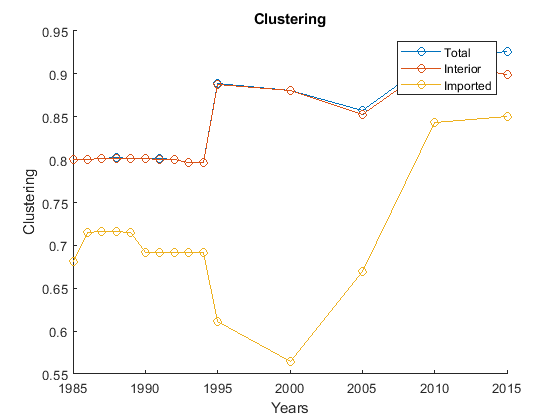

%Metrics

%Clustering 
figure();
hold on;
arrayfun(@(x) plot(yrs,C(:,x),'-o'),1:3)
legend(names);
title('Clustering')
xlabel('Years')
ylabel('Clustering')
hold off;

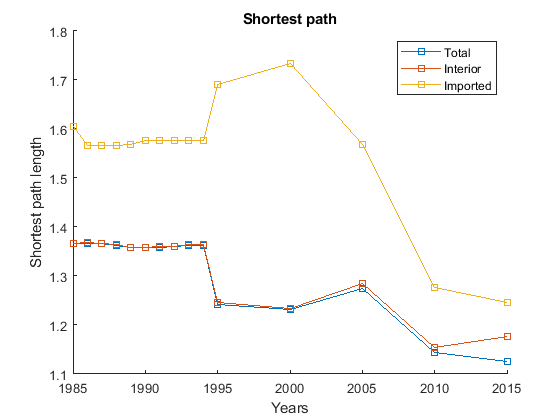


%Shortest path
figure();
hold on;
arrayfun(@(x) plot(yrs,dist(:,x),'-s'),1:3)
legend(names);
title('Shortest path')
xlabel('Years')
ylabel('Shortest path length')
hold off;

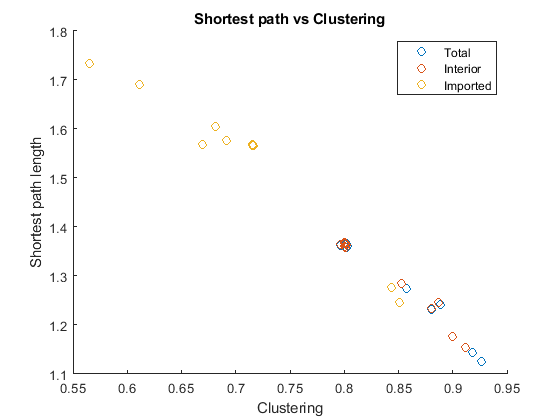


%spl vs C

figure();
hold on;
arrayfun(@(x) plot(C(:,x),dist(:,x),'o'),1:3)
legend(names);
title('Shortest path vs Clustering')
xlabel('Clustering')
ylabel('Shortest path length')
hold off;

function IO = normalize(IO_S)
    IO_S = IO_S - diag(diag(IO_S));
    %Linear normalization of the weights w in [0,1]
    IO = ((IO_S)/(max(max(IO_S)) - min(min(IO_S))));
end